## Clean the workspace

clearvars 
addpath("layer configs");

Config setup

engine = "trainnet";    
net    = "conv6layers";   
mm     = "sgdm";      

lr   =0.1;     
mb   =128;    
ep   =300;    
mo   = 0.9;     
l2   =0.0005;    
dr   =80;     
lrdf = 0.1;     
vp   = 40;      
CheckpointEnable = true;
ckptEvery = 10;

%% Build the single config + confirm

cfg = struct('net',net, 'engine',engine, 'mm',mm, 'lr',lr, 'mb',mb, 'ep',ep, ...
    'mo',mo, 'l2',l2, 'dr',dr, 'lrdf',lrdf, 'vp',vp);
configs = repmat(cfg, 1,4);

## Load the training data

loadtrainingdata
cn = categories(trainLabels);

## Set up the result holders

numRuns = numel(configs);
accTest = zeros(numRuns+2,1);
macroPrecisionTest = zeros(numRuns+2,1);
macroRecallTest = zeros(numRuns+2,1);
macroF1Test = zeros(numRuns+2,1);

## Loop through the configurations

for expNum = 1:numRuns
    fprintf('\n=== Running Experiment %d ===\n', expNum);


=== Running Experiment 1 ===



=== Running Experiment 2 ===



=== Running Experiment 3 ===



=== Running Experiment 4 ===


Clean up from the previous experiment

    clearvars -except engine configs numRuns cn ...
        accTest macroPrecisionTest macroRecallTest macroF1Test ...
        expNum trainImages valImages testImages ...
        trainLabels valLabels testLabels ...
        imageAugmenter trainDS valDS testDS ckpt ckptEvery

Set up the variables used

    cfg = configs(expNum)
    disp(cfg)
    rng(expNum, 'twister');

cfg = struct with fields:
       net: "conv6layers"
    engine: "trainnet"
        mm: "sgdm"
        lr: 0.1000
        mb: 128
        ep: 300
        mo: 0.9000
        l2: 5.0000e-04
        dr: 80
      lrdf: 0.1000
        vp: 40

       net: "conv6layers"
    engine: "trainnet"
        mm: "sgdm"
        lr: 0.1000
        mb: 128
        ep: 300
        mo: 0.9000
        l2: 5.0000e-04
        dr: 80
      lrdf: 0.1000
        vp: 40


cfg = struct with fields:
       net: "conv6layers"
    engine: "trainnet"
        mm: "sgdm"
        lr: 0.1000
        mb: 128
        ep: 300
        mo: 0.9000
        l2: 5.0000e-04
        dr: 80
      lrdf: 0.1000
        vp: 40

       net: "conv6layers"
    engine: "trainnet"
        mm: "sgdm"
        lr: 0.1000
        mb: 128
        ep: 300
        mo: 0.9000
        l2: 5.0000e-04
        dr: 80
      lrdf: 0.1000
        vp: 40


cfg = struct with fields:
       net: "conv6layers"
    engine: "trainnet"
        mm: "sgdm"
        lr: 0.1000
        mb: 128
        ep: 300
        mo: 0.9000
        l2: 5.0000e-04
        dr: 80
      lrdf: 0.1000
        vp: 40

       net: "conv6layers"
    engine: "trainnet"
        mm: "sgdm"
        lr: 0.1000
        mb: 128
        ep: 300
        mo: 0.9000
        l2: 5.0000e-04
        dr: 80
      lrdf: 0.1000
        vp: 40


cfg = struct with fields:
       net: "conv6layers"
    engine: "trainnet"
        mm: "sgdm"
        lr: 0.1000
        mb: 128
        ep: 300
        mo: 0.9000
        l2: 5.0000e-04
        dr: 80
      lrdf: 0.1000
        vp: 40

       net: "conv6layers"
    engine: "trainnet"
        mm: "sgdm"
        lr: 0.1000
        mb: 128
        ep: 300
        mo: 0.9000
        l2: 5.0000e-04
        dr: 80
      lrdf: 0.1000
        vp: 40


Set up the layers


    layers = feval(cfg.net, 10);
    if isa(layers,'nnet.cnn.LayerGraph')
        co = numel(layers.Layers);
    else
        co = numel(layers);
    end

Checkpoints 

    vf = floor(numel(trainLabels)/cfg.mb);     % iterations per epoch
    ep = cfg.ep;                               % epochs to run (reduced on resume)

    if CheckpointEnable
        tag      = sprintf('%s_%s_E%d_BS%d', cfg.net, cfg.engine, cfg.ep, cfg.mb);
        ckptPath = fullfile('Test Output','checkpoints', tag);
        if ~isfolder(ckptPath), mkdir(ckptPath); end   % CheckpointPath must already exist

        % Resume from the latest checkpoint in this folder, if there is one
        cps = dir(fullfile(ckptPath,'net_checkpoint__*.mat'));
        if ~isempty(cps)
            [~,ix] = max([cps.datenum]);
            S  = load(fullfile(ckptPath, cps(ix).name));
            fn = fieldnames(S);  loaded = S.(fn{1});
            for i = 1:numel(fn)
                if isa(S.(fn{i}),'dlnetwork') || isa(S.(fn{i}),'DAGNetwork') || isa(S.(fn{i}),'SeriesNetwork')
                    loaded = S.(fn{i});  break;
                end
            end
            layers = loaded;
            tok    = regexp(cps(ix).name,'net_checkpoint__(\d+)__','tokens','once');
            epDone = floor(str2double(tok{1}) / vf);
            ep     = max(1, cfg.ep - epDone);
            fprintf('Resuming "%s" from epoch %d -> %d epochs remaining\n', tag, epDone, ep);
        end
    end

 Set up the training options 

    % trainnet's accuracy metric needs one-hot validation targets; trainNetwork takes categorical as-is
    if cfg.engine == "trainnet"
        valForOpts = transform(valDS, @(d) mixupTransform(d, numel(cn), 0, 0, cn));
    else
        valForOpts = valDS;
    end
    options = createTrainingOptions(cfg.mm,cfg.lr,cfg.dr,ep,cfg.mb,valForOpts,vf,cfg.mo,1,cfg.lrdf,cfg.l2,cfg.vp,cfg.engine,ckptPath,ckptEvery);

 Run the training

        55100      157       02:06:26     0.047916          1.7536                                    60.156                          
        55107      157       02:06:29     0.047916          1.2609           0.53797                  86.719                    87.559
        55150      158       02:06:37     0.047383         0.74223                                    88.281                          
        55200      158       02:06:46     0.047383          0.9074                                    85.156                          
        55250      158       02:06:53     0.047383         0.90236                                    84.375                          
        55300      158       02:07:00     0.047383         0.80012                                      87.5                          
        55350      158       02:07:07     0.047383          0.9132                                    82.031                          
        55400      158       02:07:14     0.047383     

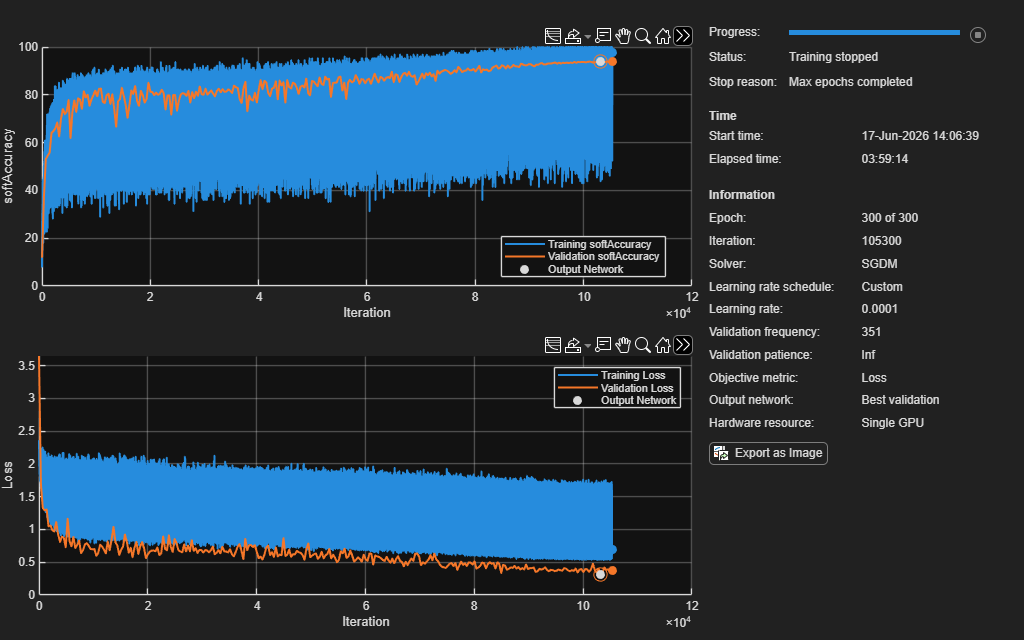


=== Running Training 2 (trainnet) ===
    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingsoftAccuracy    ValidationsoftAccuracy
    _________    _____    ___________    _________    ____________    ______________    ____________________    ______________________
            0        0       00:00:02         0.03                            4.4892                                            10.449
            1        1       00:00:02         0.03          2.3357                                     9.375                          
           50        1       00:00:11         0.03          2.0327                                    22.656                          
          100        1       00:00:17         0.03          2.0324                                     31.25                          
          150        1       00:00:23         0.03          1.9191                                    36.719                          
          200   


=== Running Training 3 (trainnet) ===
    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingsoftAccuracy    ValidationsoftAccuracy
    _________    _____    ___________    _________    ____________    ______________    ____________________    ______________________
            0        0       00:00:02         0.03                            4.8328                                            8.0859
            1        1       00:00:02         0.03          2.3231                                      12.5                          
           50        1       00:00:11         0.03          2.1927                                    22.656                          
          100        1       00:00:17         0.03          1.8935                                    32.812                          
          150        1       00:00:23         0.03          1.9525                                    32.031                          
          200   

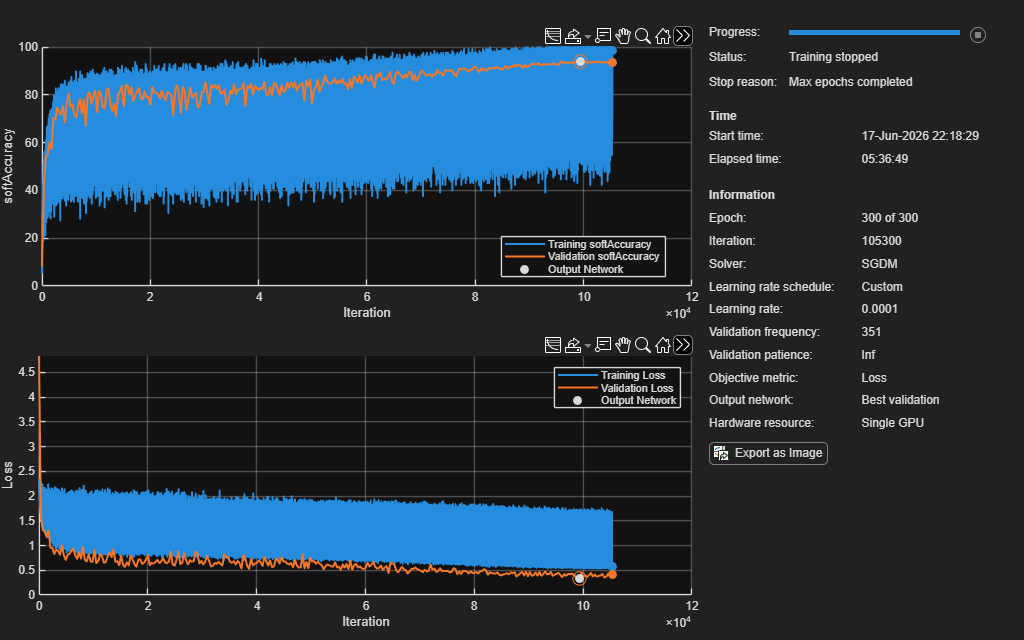


=== Done Training 3 ===
accuarcy = 93.5900 %

        80100      229       02:43:01     0.013799         0.89557                                    90.625                          
        80150      229       02:43:08     0.013799         0.65089                                    98.438                          
        80200      229       02:43:16     0.013799          1.7463                                    58.594                          
        80250      229       02:43:24     0.013799         0.66357                                    95.312                          
        80300      229       02:43:31     0.013799          1.6468                                    69.531                          
        80350      229       02:43:38     0.013799         0.70261                                    92.188                          
        80379      229       02:43:43     0.013799         0.78557           0.46454                  89.844                     90.43
        80400      230       02:43:45     0.013434     

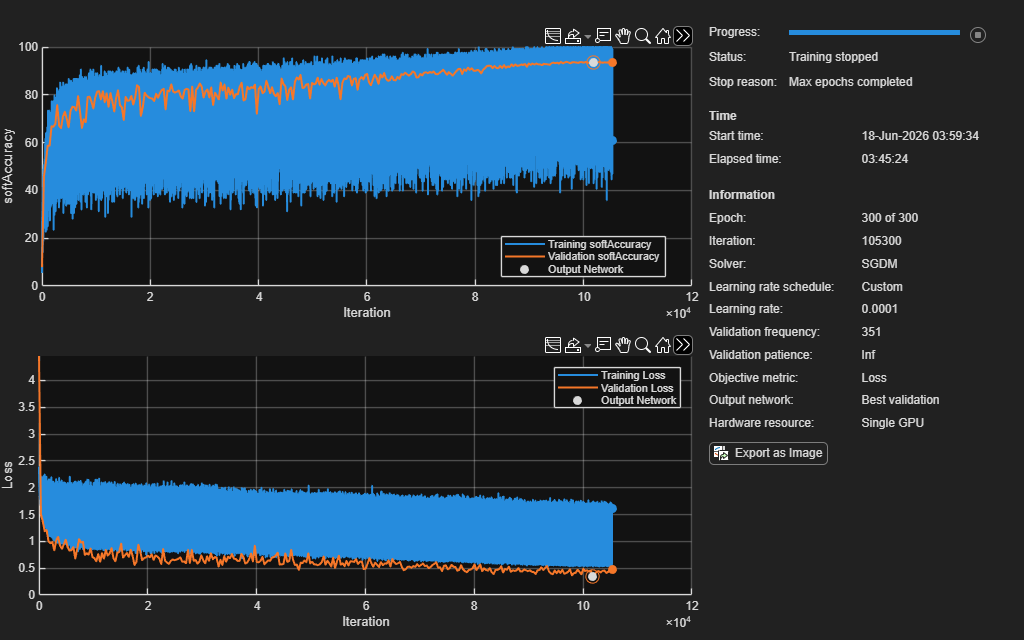


    [net,outputFolder,baseFilename] = runfile(trainDS,testDS,testLabels,layers,options,cfg.mm,co,expNum,true,true,cfg.engine,cn,[],ckptPath);

Calculating the metrics

    [testev,~] = evaluateClassification(net,testLabels,testDS,outputFolder,baseFilename,1,"Testing");
    accTest(expNum)            = testev(1)*100
    macroPrecisionTest(expNum) = testev(2)*100
    macroRecallTest(expNum)    = testev(3)*100
    macroF1Test(expNum)        = testev(4)*100

    figCM = figure('Name',sprintf('Run %d Confusion Matrices', expNum),'NumberTitle','off');
    set(figCM, 'Position', [100 100 4000 12000]);   % wide layout: 3 subplots side by side

accTest =    93.9400
         0
         0
         0
         0
         0


macroPrecisionTest =    93.9457
         0
         0
         0
         0
         0


macroRecallTest =    93.9400
         0
         0
         0
         0
         0


macroF1Test =    93.9260
         0
         0
         0
         0
         0


accTest =    93.9400
   92.7300
         0
         0
         0
         0


macroPrecisionTest =    93.9457
   92.8224
         0
         0
         0
         0


macroRecallTest =    93.9400
   92.7300
         0
         0
         0
         0


macroF1Test =    93.9260
   92.7490
         0
         0
         0
         0


accTest =    93.9400
   92.7300
   93.5900
         0
         0
         0


macroPrecisionTest =    93.9457
   92.8224
   93.5898
         0
         0
         0


macroRecallTest =    93.9400
   92.7300
   93.5900
         0
         0
         0


macroF1Test =    93.9260
   92.7490
   93.5684
         0
         0
         0


accTest =    93.9400
   92.7300
   93.5900
   93.8700
         0
         0


macroPrecisionTest =    93.9457
   92.8224
   93.5898
   93.8658
         0
         0


macroRecallTest =    93.9400
   92.7300
   93.5900
   93.8700
         0
         0


macroF1Test =    93.9260
   92.7490
   93.5684
   93.8517
         0
         0


Training

    [trev,cmTrain] = evaluateClassification(net,trainLabels,trainDS,outputFolder,baseFilename,0,"training");
    subplot(1,3,1); confusionchart(cmTrain);
    title(sprintf('Training CM (Run %d), acc = %.3f %%', expNum, trev(1)*100));

Validation

    [vaev,cmVal] = evaluateClassification(net,valLabels,valDS,outputFolder,baseFilename,0,"validation");
    subplot(1,3,2); confusionchart(cmVal);
    title(sprintf('Validation CM (Run %d), acc = %.3f %%', expNum, vaev(1)*100));

Test

    [~,cmTest] = evaluateClassification(net,testLabels,testDS,outputFolder,baseFilename,0,"Testing");
    subplot(1,3,3); confusionchart(cmTest);
    title(sprintf('Testing CM (Run %d), acc = %.3f %%', expNum, testev(1)*100));
    [~,~] = ttaPredict(net,8);


=== TTA (9 views): acc 95.10% | P 95.10% | R 95.10% | F1 95.10% ===



=== TTA (9 views): acc 94.18% | P 94.26% | R 94.18% | F1 94.20% ===



=== TTA (9 views): acc 94.87% | P 94.87% | R 94.87% | F1 94.86% ===



=== TTA (9 views): acc 94.92% | P 94.92% | R 94.92% | F1 94.92% ===


Save high-resolution PNG and PDF

    exportgraphics(figCM, fullfile(outputFolder, sprintf('ConfusionMatrices_Run%d.png',expNum)), 'Resolution', 300);
    exportgraphics(figCM, fullfile(outputFolder, sprintf('ConfusionMatrices_Run%d.pdf',expNum)), 'Resolution', 300);
end

## Calculating the mean and standard deviation

accTest(numRuns+1)            =   mean(accTest(1:numRuns));
macroPrecisionTest(numRuns+1) =   mean(macroPrecisionTest(1:numRuns));
macroRecallTest(numRuns+1)    =   mean(macroRecallTest(1:numRuns));
macroF1Test(numRuns+1)        =   mean(macroF1Test(1:numRuns));
accTest(numRuns+2)            =   std(accTest(1:numRuns));
macroPrecisionTest(numRuns+2) =   std(macroPrecisionTest(1:numRuns));
macroRecallTest(numRuns+2)    =   std(macroRecallTest(1:numRuns));
macroF1Test(numRuns+2)        =   std(macroF1Test(1:numRuns));

## Convert to percentages and display the results table

accTest            = round(accTest(:), 3);
macroPrecisionTest = round(macroPrecisionTest(:), 3);
macroRecallTest    = round(macroRecallTest(:), 3);
macroF1Test        = round(macroF1Test(:), 3);

rowNames = [arrayfun(@(x) sprintf('Run %d', x), 1:numRuns, 'UniformOutput', false), ...
            {'Mean', 'Std'}];

resultsTable = table(accTest(:), macroPrecisionTest(:), macroRecallTest(:), macroF1Test(:), ...
    'VariableNames', {'Accuracy(%)', 'Precision(%)', 'Recall(%)', 'F1-score(%)'}, ...
    'RowNames', rowNames);

disp(resultsTable);

             Accuracy(%)    Precision(%)    Recall(%)    F1-score(%)
             ___________    ____________    _________    ___________
    Run 1       93.94          93.946         93.94        93.926   
    Run 2       92.73          92.822         92.73        92.749   
    Run 3       93.59           93.59         93.59        93.568   
    Run 4       93.87          93.866         93.87        93.852   
    Mean       93.533          93.556        93.533        93.524   
    Std         0.556           0.512         0.556         0.539   
